xmin = -1; xmax = 1;
F = -1;

NEL = 2^8; 
hx = (xmax-xmin)/NEL;

dirichlet = [1 NEL+1];
fc_gD = @(x) 0;

% mesh
vertex_coordinates = (xmin:hx:xmax)';
elem_vertices = zeros(NEL,2);
for i=1:NEL
    elem_vertices(i,:) = [i,i+1];
end

dof = 2*(NEL+1);

A = sparse(dof,dof);
fh = zeros(dof,1);

master_el_mat = load('master_stiff_1d.mat').Kel1d;
el_area = hx;

for el=1:NEL
    el_mat = 1/el_area^3*master_el_mat;
    v_elem = elem_vertices(el,:);
    v_elem_full = [2*v_elem(1)-1:2*v_elem(1) 2*v_elem(2)-1:2*v_elem(2)];
    A(v_elem_full,v_elem_full) = A(v_elem_full,v_elem_full) + el_mat;
end

fh(1:2:end) = F*ones(NEL+1, 1); fh(1) = fh(1)/2; fh(end-1) = fh(end-1)/2;
fh = fh * el_area;
% save('stiffness_matrix_1d.mat','A');
% save('load_vector_1d.mat','fh');
% full(A)

% dirichlet cond
for i = 1:length(dirichlet)
    diri = dirichlet(i);
    diri_full = 2*diri(1)-1:2*diri(1);
    numcond = 2;
    A(diri_full,:) = zeros(numcond, dof);
    A(:,diri_full) = zeros(dof, numcond);
    for j=1:numcond
        A(diri_full(j), diri_full(j)) = 1;
    end
    fh(diri_full) = fc_gD(vertex_coordinates(diri, :));
end


tic;
uh = A \ fh;
toc

Elapsed time is 0.009958 seconds.


% eigsA = eig(A);
% plot((1:length(eigsA))/length(eigsA),eigsA)

save('stiffness_matrix_1d.mat','A');
save('load_vector_1d.mat','fh');
% save('uh_small.mat','uh');

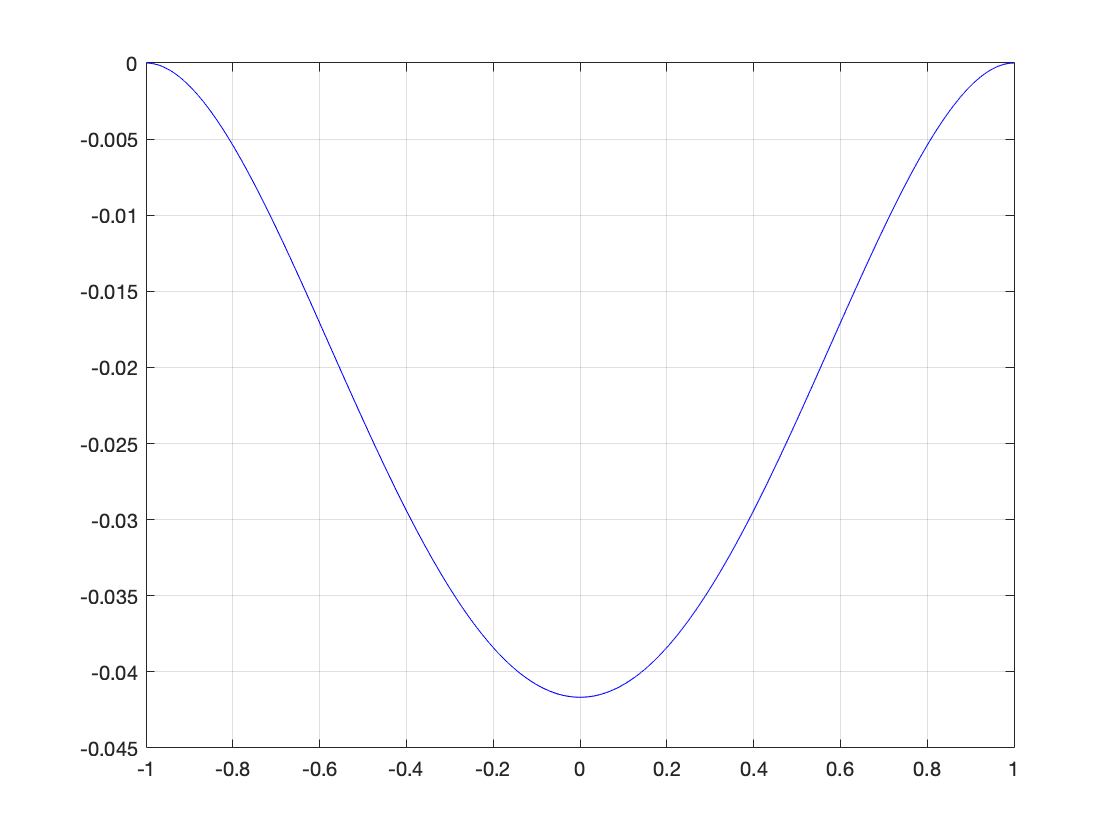

plotptsnum = 128;
xs = linspace(xmin,xmax,plotptsnum+1);

figure 
plot(vertex_coordinates, uh(1:2:end),'b-')
grid on